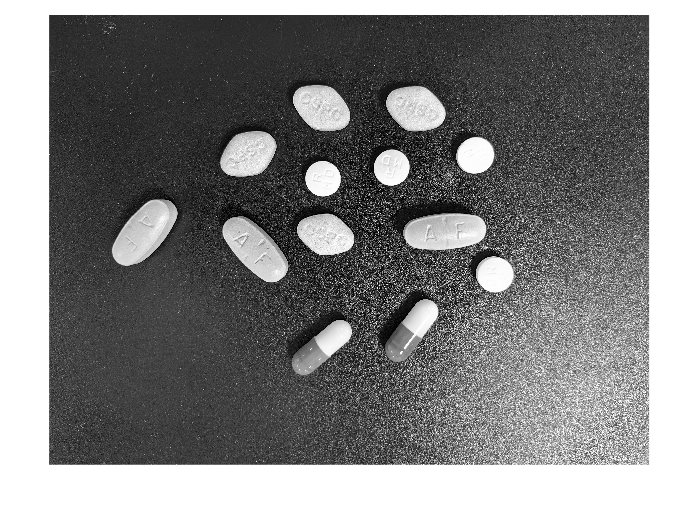

% 读取图像
I = imread("C:\Users\27492\Desktop\IMG\演示作业\药片1.jpg");
%转化为灰度图像
I1 = rgb2gray(I);
imshow(I1);

D5=28

D5 = 28

se14 = strel('disk',D5)

se14 = strel 是具有以下属性的 disk 形结构元素:

      Neighborhood: [55×55 logical]
    Dimensionality: 2


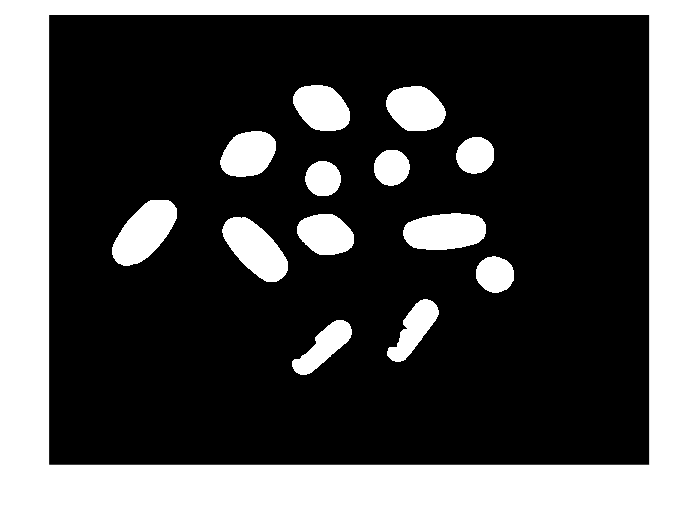

BW = imopen(I1,se14);
%将灰度图像转化为二值图像
C3=imbinarize(BW);
imshow(C3);

紫色药片

%紫色药片
function [BW_out,properties] = filterRegions_1(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 08-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[100000, 118751]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Circularity', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
end
Q1 = filterRegions_1(C3)

Q1 = 3000×4000 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

 [L,num]=bwlabel(Q1);
 %输出对象数量
 disp(['紫色药片的数目',num2str(num)]);

紫色药片的数目3


黄色菱形药片

 function [BW_out,properties] = filterRegions_2(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 08-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[79000, 100000]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Circularity', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
 end
 Q2= filterRegions_2(C3);
 [L,num2]=bwlabel(Q2);
 %输出对象数量
 disp(['黄色菱形药片的数目',num2str(num2)]);

黄色菱形药片的数目4


白色圆形小药片

 function [BW_out,properties] = filterRegions_3(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 08-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[42000, 50000]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Circularity', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
 end
 Q3= filterRegions_3(C3);
  [L,num3]=bwlabel(Q3);
 %输出对象数量
 disp(['白色圆形小药片的数目',num2str(num3)]);

白色圆形小药片的数目4


胶囊数目

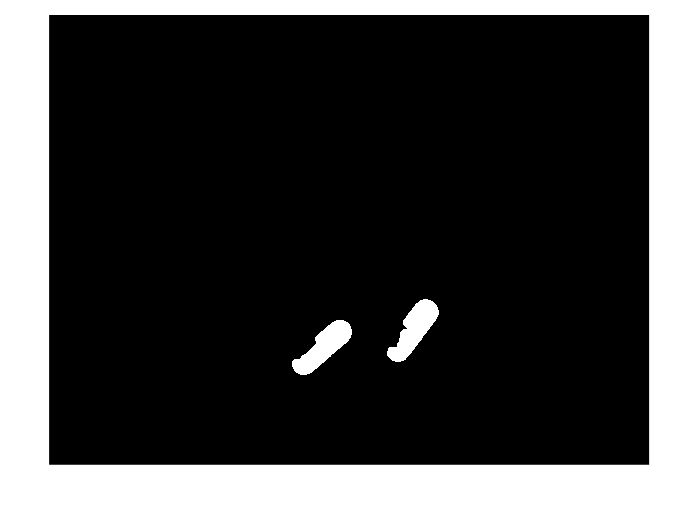

 function [BW_out,properties] = filterRegions_4(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 08-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[50000, 73000]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Circularity', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
 end
  Q4= filterRegions_4(C3);
  imshow(Q4)

  [L,num4]=bwlabel(Q4);
 %输出对象数量
 disp(['胶囊的数目',num2str(num4)]);

胶囊的数目2
